# Práctica 4

## I. Histograma y umbralización

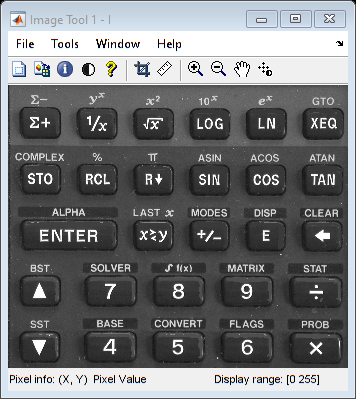

I = imread('calculadora.tif');
imtool(I)

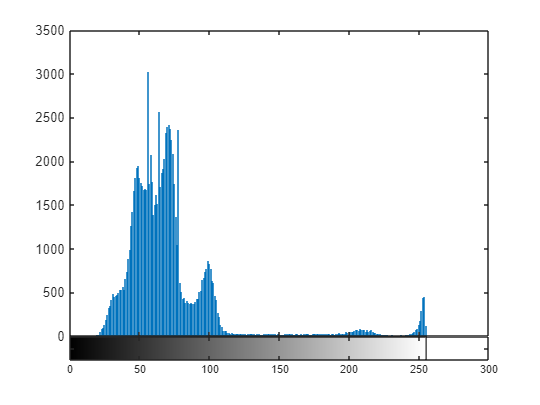


%% Representación del histograma
figure, imhist(I); axis('auto')

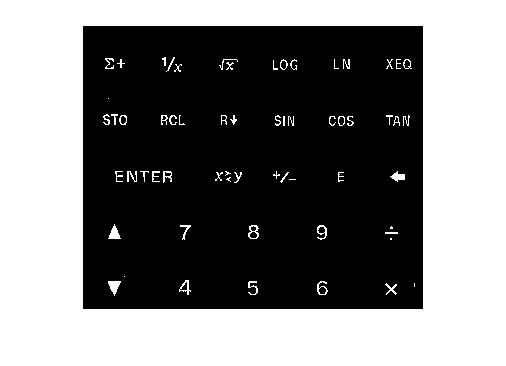


%% Umbralizar
I_U = im2bw(I, 230/255);
figure, imshow(I_U);

## II. Segmentación y caracterización de regiones

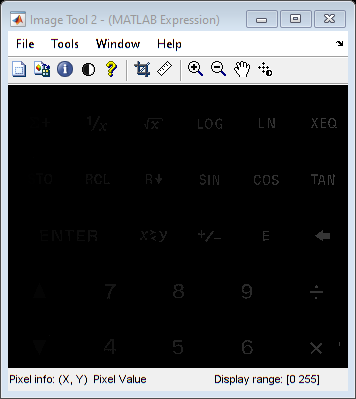

[Seg_I_U, Nobjetos] = bwlabel(I_U);   % Seg_I_U es la capa de segmentación
imtool(uint8(Seg_I_U))


disp('El número de objetos es: ')

El número de objetos es: 


Nobjetos

Nobjetos = 61

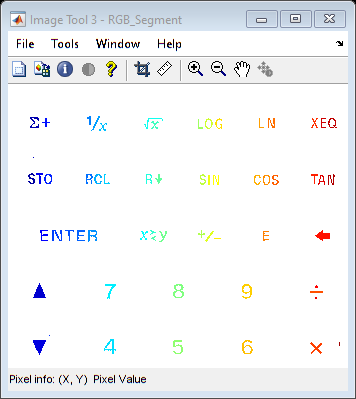


RGB_Segment = label2rgb(Seg_I_U);
imtool(RGB_Segment)

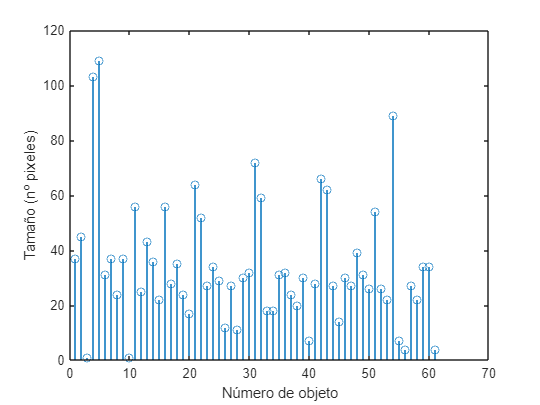


Props = regionprops(Seg_I_U, 'Area');  %% Para dar el valor de un campo: Props(1).Area

V_Area = [];
for ind_obj=1:Nobjetos                 %% Extracción de las areas del struct
    V_Area = [V_Area Props(ind_obj).Area];
end

figure, stem(V_Area)
xlabel('Número de objeto'), ylabel('Tamaño (nº pixeles)')


% Identificamos las etiquetas que hay que quitar (p.e, umbral de 5 píxeles)
V_No_Interes = [3 10 61]         %% Se puede automatizar

V_No_Interes =      3    10    61


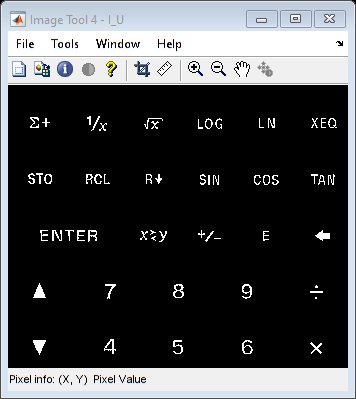


% Filtrar de a imagen binaria las regiones de no interés.
[n_filas, n_cols] = size (I_U);

for ind_nfila = 1:n_filas
    for ind_ncol = 1:n_cols
        if I_U(ind_nfila, ind_ncol)
            numero_et = Seg_I_U(ind_nfila, ind_ncol);
            if sum(ismember(V_No_Interes, numero_et)) > 0
                I_U(ind_nfila, ind_ncol) = 0;
            end
        end
    end
end

imtool(I_U);

## III. Procesado para identificación de la tecla “Enter”

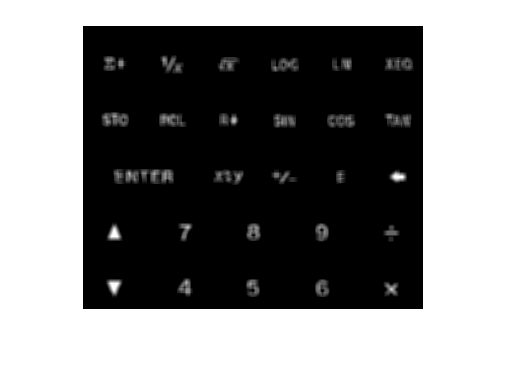

% Filtro de media sobre I_U (imagen binaria con objetos filtrados) para unir regiones
% Definición de la máscara
h= 1/(5*5)*ones(5,5);
I_U_Fmedia = imfilter(255*uint8(I_U), h);
figure, imshow(I_U_Fmedia)

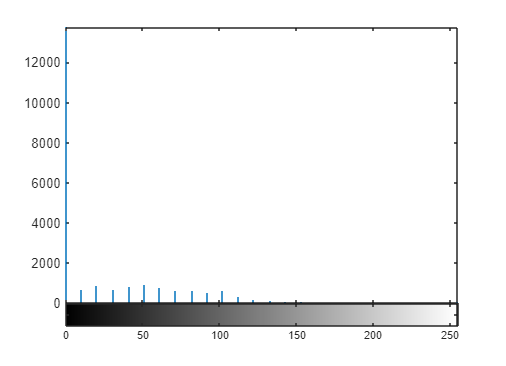

imhist(I_U_Fmedia)

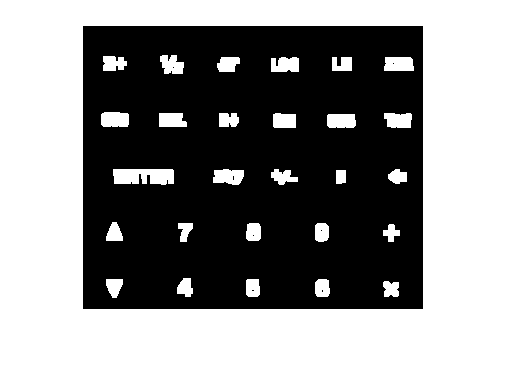


%% Umbralizar la imagen
I_U_Fmedia_Th = im2bw(I_U_Fmedia, 1/255);
figure, imshow(I_U_Fmedia_Th);


% Segmentación binaria (busco grupos conexos de pixeles de primer plano)
[Segm_regs_teclas, Nteclas] = bwlabel(I_U_Fmedia_Th);
Nteclas

Nteclas = 27

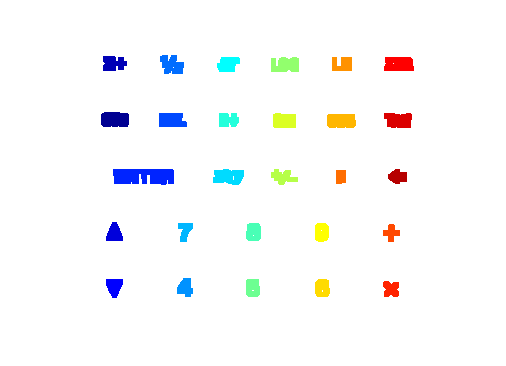

RGB_Segment = label2rgb(Segm_regs_teclas);
figure, imshow(RGB_Segment)     % Imagen en falso color de la capa de etiquetas

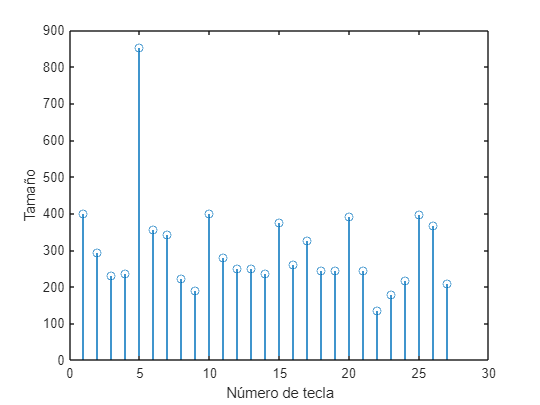


Props = regionprops(Segm_regs_teclas, 'Area');
V_Area = [];
for ind_obj=1:Nteclas
    V_Area = [V_Area Props(ind_obj).Area];
end

figure, stem(V_Area)
xlabel('Número de tecla')
ylabel('Tamaño')


%% Identificamos el objeto más grande
I_U_Fmedia_Th_BIS = I_U_Fmedia_Th;

% La etiqueta de interés es la etiqueta 5
Label_interes = 5

Label_interes = 5

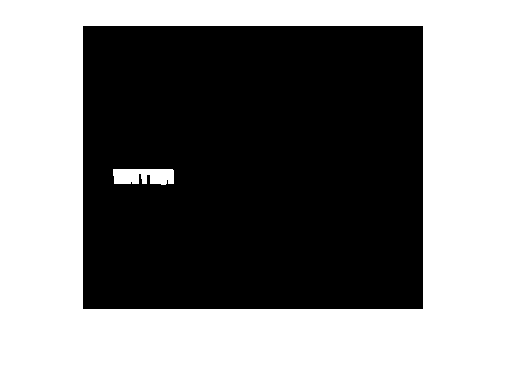

[n_filas, n_cols] = size(I_U_Fmedia_Th);

for ind_nfila=1:n_filas
    for ind_ncol=1:n_cols
        if (Segm_regs_teclas(ind_nfila,ind_ncol)~= Label_interes) % Alt + 126 = ~
            I_U_Fmedia_Th_BIS(ind_nfila,ind_ncol) = 0;
        end
    end
end

figure, imshow(I_U_Fmedia_Th_BIS)

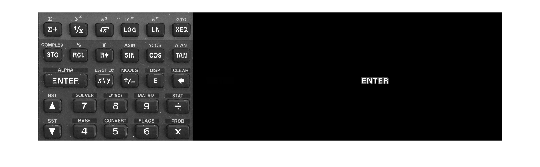


gris_Th = uint8(I_U_Fmedia_Th_BIS);
I_Enter = gris_Th .* I;
figure, imshow([I, gris_Th, I_Enter])